# Exercises 5.4

2. The two-element mesh at right was designed for a plane stress analysis.Each element has dimensions 1 m ×1 m and thikness equal to 0.2 m. Only self weight is considered in the analysis where γ= 25kN/m3.With the aid of computer software calculate nodal displacements and reaction forces. Consider full integration. The material properties are E= 20GPa and ν= 0.25.

clear all
clc

## Material

E    = 20e6;                          % Modulo de Young [Kpa]
nu   = 0.25;                          % Poisson
q    = 4;                             % Pontos de integração [1 4 9 16]
type = 4;                             % Nós por elemento [4 8 12]
h    = 1;                           % Espessura [m]        
D    = E/(1-nu^2)*[1 nu 0;
                   nu 1 0;
                   0 0 (1-nu)/2];     %Matriz D

## Malha

Lx = 2;                               % Comprimento em x
Ly = 2;                               % Comprimento em y
Elemx = 1;                            % Divião da malha em x
Elemy = 1;                            % Divião da malha em y
[nos, elem] = quad_mesh(Lx,Ly, Elemx,Elemy, type); % Coordenada de cada nó e numeração dos nos de cada elemento 

## Apoios

Restr = [1 1 1; (Elemx+1) 0 1];      % NumNó, Rx, Ry [y=1 n=0]

## Força de corpo

gamma = -25;                          % Peso Própio [kN/m³] 

## Montagem

NumElem  = size(elem, 1);             % Número de elementos
Ndof     = 2;                         % Número de graus de liberdade
NoElem   = size(elem, 2);             % Número de Nós por elemento
NumNos   = size(nos, 1);              % Número de Nós
GL       = size(nos, 1) * Ndof;       % Graus de liberdade
K        = zeros(GL, GL);             % Matriz de rigides com 0
U        = zeros(GL, 1);              % Vetor de deslocamentos com 0
F        = zeros(GL, 1);              % Vetor de forças com 0
Fr       = zeros(GL, 1);              % Vetor de reações com 0

coor     = zeros(NumElem, NoElem*Ndof);     % ...
k=1;
for i = [linspace(1, NoElem*Ndof-1, NoElem)]
    coor(:,[i i+1]) = [elem(:, k)*2-1, elem(:, k)*2]; % Matriz de coordenadas
    k=k+1;
end
% coor = sort(coor, NumElem);

## Matriz K e F

for i = 1: NumElem
    C = [nos(elem(i,:), :)];                    % Matriz de coordenadas por elemento
    Ke = compute_K(C, D, q, h, NoElem);         % Matriz de rigidez por elemtno
    K(coor(i, :), coor(i, :)) = ... 
        K(coor(i, :), coor(i, :)) + ...
        Ke;                                     % Matriz de rigidez global
    Fex = body_forces(C, h, gamma, q, NoElem);   % Forças de corpo por elemento
    F(elem(i,:)*2) = F(elem(i,:)*2) + Fex;       %vetor global de forças de corpo
    Ft = F + [0 0 0 0 0 -10 0 -10]';      
end

## Restrições nos apoios

NumGLR = sum(sum(Restr(:, [2 3])));            % Determinação do número de restrições
GLR = zeros(NumGLR, 1);                        % Vetor deslocamentos restringidos 

## Coordenadas com restiçoes

i = 1;
for apoio = 1:(size(Restr, 1)) 
    NoApoio = Restr(apoio, 1);          % Nó de apoio
    if Restr(apoio, 2) == 1
        GLR(i, 1) = NoApoio * 2 - 1;    % Restrição em x
        i = i + 1;
    end    
    if Restr(apoio, 3) == 1
        GLR(i, 1) = NoApoio * 2 - 0;    % Restrição em y
        i = i + 1;
    end
end

## Cordenadas sem restrição

GLSR = setxor((1:GL)', GLR);             % Grau de liberdade sem restrição

## Deslocamentos sem restição

U(GLSR) = K(GLSR, GLSR) \ Ft(GLSR);       % Deslocamentos

## Forças de reação

Fr(GLR) = K(GLR, :) * U;                 % Força de reação

## Gráfico

Ux = U(1:2:GL);
Uy = U(2:2:GL);
if type == 4
    T = 'Q4';
elseif type == 8
    T = 'Q8';
else
    T = 'Q12';
end

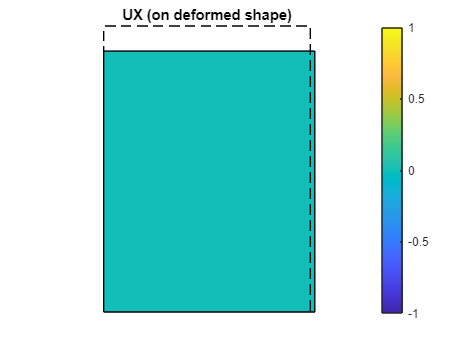

scaleFactor = 50000;
figure
draw_field(nos+scaleFactor*[Ux Uy],elem,T,Ux);
draw_mesh(nos+scaleFactor*[Ux Uy],elem,T,'-');
hold on
draw_mesh(nos+scaleFactor*[Ux Uy],elem,T,'-');
draw_mesh(nos,elem,T,'--');
axis off
colorbar
title('UX (on deformed shape)')
hold off

# Exercises 5.4

3. In the last exercise, calculate the strain and stress vectors at the in-tegration points of element 1.

## Tensor

[sig] = stress_strain(nos, elem, U, D, q, coor);

## Gráfico

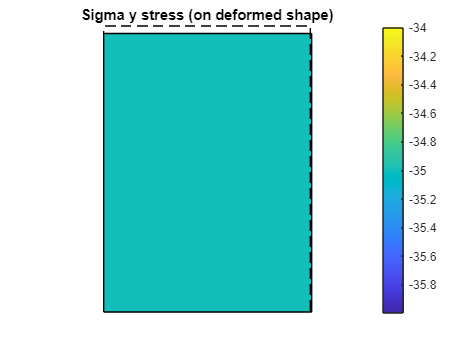

scaleFactor = 15000;
figure
draw_field(nos+scaleFactor*[Ux Uy],elem,T,sig(:,:,2));
draw_mesh(nos+scaleFactor*[Ux Uy],elem,T,'-');
hold on
draw_mesh(nos+scaleFactor*[Ux Uy],elem,T,'-');
draw_mesh(nos,elem,T,'--');
axis off
colorbar
title('Sigma y stress (on deformed shape)')

# Exercises 5.4

4. Verify if the analytical vertical stress γh at the bottom of the structure can be recovered from the stresses at ingration points.

Não pode